# Manejo del transiente del filtro

El proceso de conformación de pulso consiste en la convolución del tren de impulsos desplazados con la forma de onda del pulso. 

En su aplicación se debe tener en cuanta la respuesta transitoria de los filtros, es decir, un corrimiento temporal de la señal. 

Para entender mejor este problema se presenta el siguiente código. 

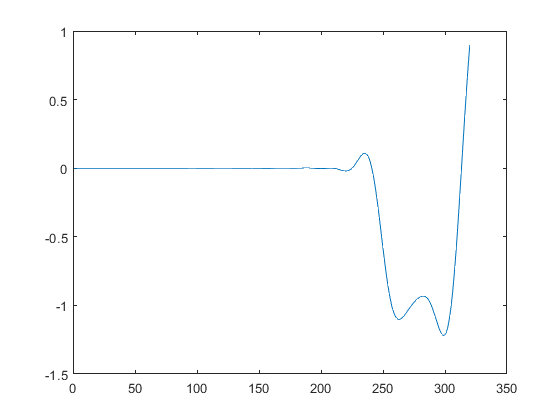

% implementación de los filtros
s=randsrc(1, 20, [-1 1]); %secuencia de símbolos 4-PAM 

%Filtro Conformador 
%U sobremuestreo
%R roll-off
%L*U debe dar un número par 
R=0.5 ; U=16; L=8; T=1;
h1 = rcosfir(R, L, U, T,'sqrt') ; %la longitud del filtro es 2*L*U+1
% upsample 
su1=upsample(s,U);
%filtraje
x1=filter(h1,1,su1); 
%se filtra 2 veces, en el transmisor y en el receptor
x1=filter(h1,1,x1); 
figure,
plot(x1)

En la imagen se muestra el efecto del transiente, para lo cual tienen dos opciones: 

- perder los últimos símbolos y cortar tanto la señal transmitida como la recibida para poderlas comparar. 

- agregar ceros al final de la señal transmitida para no perder información, aunque también se debe cortar la señal. 

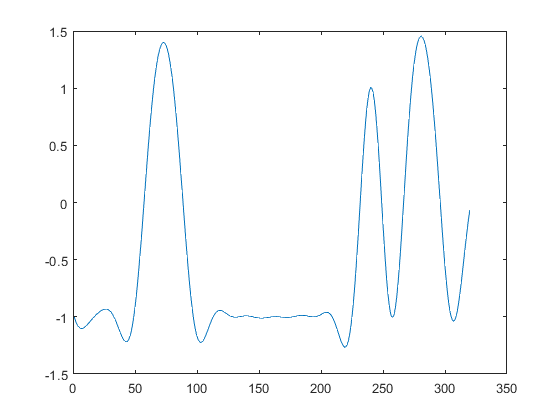

%se agregan ceros debido al transiente del filtro
su=[su1 zeros(1,2*L*U)];
x1=filter(h1,1,filter(h1,1,su));
%se cortan los ceros que se agregaron 
x1=x1(2*L*U+1:end);
%gráfica de las formas de onda resultantes
figure,
plot(x1)

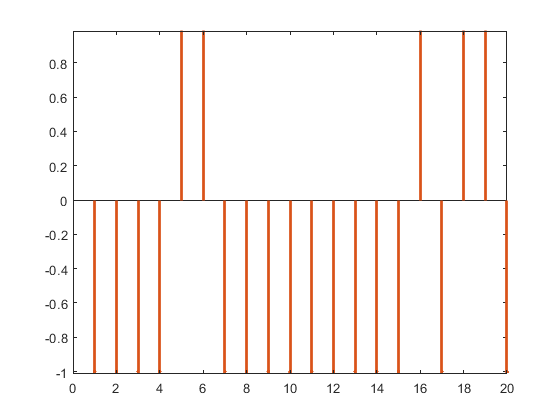

% recuperación de la secuencia original
s1=downsample(x1, U);
s1=sign(s1);
%gráfica de las secuencias recuperadas
figure,
stem(s,'.', 'linewidth', 2), hold on
stem(s1,'.', 'linewidth', 2),

isequal(s,s1)

ans = logical
   1
